# Lecture 11 Structured Illumination Microscopy

## 1. Introduction

In Lecture 6 we used scalar wave models to demonstrate the point spread function (PSF) of a diffraction-limited system for both coherent and incoherent light. In Lecture 7, we extended the discussion to three dimension. The PSF is based on the discussion using sensor-localization, i.e., the spatial resolving power is solely provided by the optics on the sensor side. 

In this lecture, we will introduce another degree of freedom in engineering the imaging system: illumination, shown in ILL. 1.1. For a source scanning system, a focused probe beam scans through the whole volume of the sample, while the sensor collects from all points uniformly. In this case, even if the measurement is responsive to an extended region (volume) in the object, i.e., no spatial resolving power, due to the localization setup. If we include both illumination engineering and optimize the sensor localization, it is possible to enhance the localization capability of only using sensor-localization. This is the essential ideal of structured illumination. Specifically, structured light can be used for improving axial resolution (optical sectioning), or improving lateral resolution (super resolution). We will expand on these two topics in Section 2 and Section 3 of this lecture, respectively.

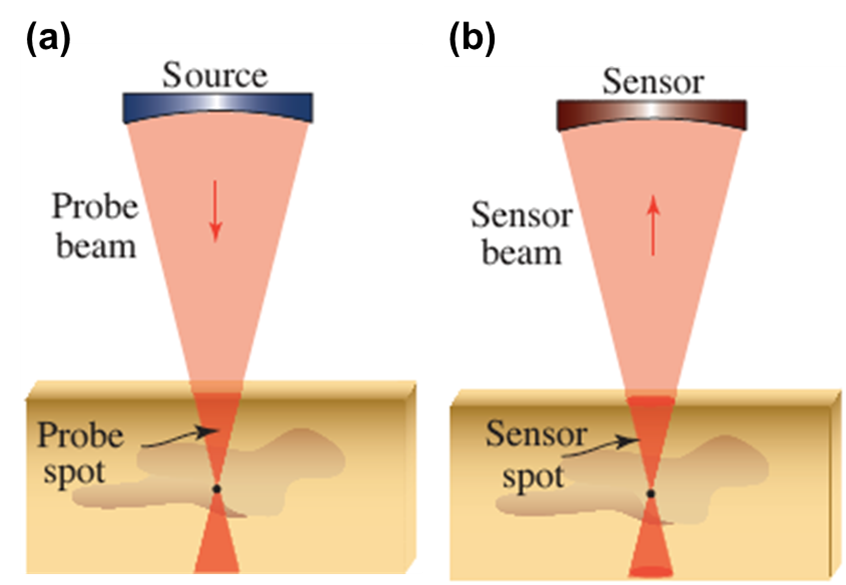

**ILL. 1.1 ***Point spread function based on (a) scanning localization vs. (b) sensor localization.*

## **2. Optical sectioning using structured illumination**

### **2.1 Localization using both illumination and detection**

From the total PSF in 2D, we can see that the PSF is the product of the detection PSF and the illumination PSF. In spatial frequency domain (k-space), this means the total transfer function is the convolution of the two transfer functions, which has greater bandwidth than either the illumination or the detection bandwidth.

However, compared to the conventional microscope (wide-field), the scanning microscope cannot take the whole image in one snapshot, leading to extended data aquisition time. Just for the slight enhancement of lateral (2D) resolution, the benefit is slim. In fact, the break-through application comes in the enhancement of depth resolution, also known as Optical sectioning.

Optical sectioning is the capability in microscopy to selectively capture a thin, two-dimensional "slice" or section of a three-dimensional (3D) sample while excluding out-of-focus information from other planes. This process is essential for obtaining clear and detailed images of biological specimens or other objects with depth, as it allows researchers to visualize specific structures within the sample without the interference of information from other focal planes.

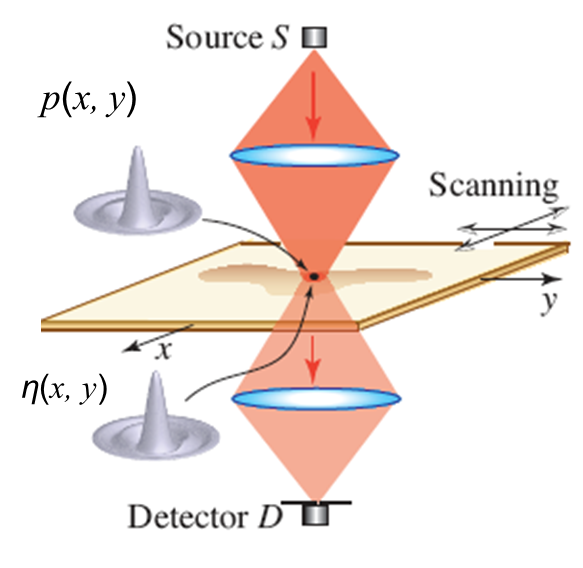

**ILL. 2.1 ***Linear model of 2D-lens based imaging system with illumination*

$p\left(x,y\right)=$ probe PSF (also called the *probe spot)*

$\eta \left(x,y\right)=$ detector receptive function (also called the *sensor spot*)

PSF of the scanning system: 


$$h\left(x,y\right)=\eta \left(x,y\right)p\left(x,y\right)$$



$$h\left(x,y\right)=\left\lbrack D\left(-x,-y\right)\otimes h_d \left(-x,-y\right)\right\rbrack \left\lbrack h_p \left(x,y\right)\otimes S\left(x,y\right)\right\rbrack$$


$\left\lbrack D\left(-x,-y\right)\otimes h_d \left(-x,-y\right)\right\rbrack$ is the sensor spot $\eta \left(x,y\right)\;$and $\left\lbrack h_p \left(x,y\right)\otimes S\left(x,y\right)\right\rbrack$ is the probe spot $p\left(x,y\right)$.

$S\left(x,y\right)$ is source distribution, $h\left(x,y\right)$ is the illumination optics' receptive function $p\left(x,y\right)=h_p \left(x,y\right)\otimes S\left(x,y\right)$.

$D\left(x,y\right)$ is detector responsivity $h_d \left(-x,-y\right)$ is the detection optics' receptive function $\eta \left(x,y\right)=D\left(-x,-y\right)\otimes h_d \left(-x,-y\right)$.

### 2.2 Confocal microscope

The first confocal scanning microscope was built by **Marvin Minsky ** in 1955 and a patent was filed in 1957. In a wide-field microscope, the whole sample is illuminated at the same time and the resulting fluorescence is detected by the microscope's camera. Particularly, the out of focus fluorescence signal, containing mainly low-frequency components, contributes to the large background.

In contrast, because the point illumination used in a confocal microscope, along with a pinhole in an optically conjugate plane in front of the detector to eliminate out-of-focus signal. Only the light produced by fluorescence very close to the focal plane can be detected, enhancing the optical sectioning.

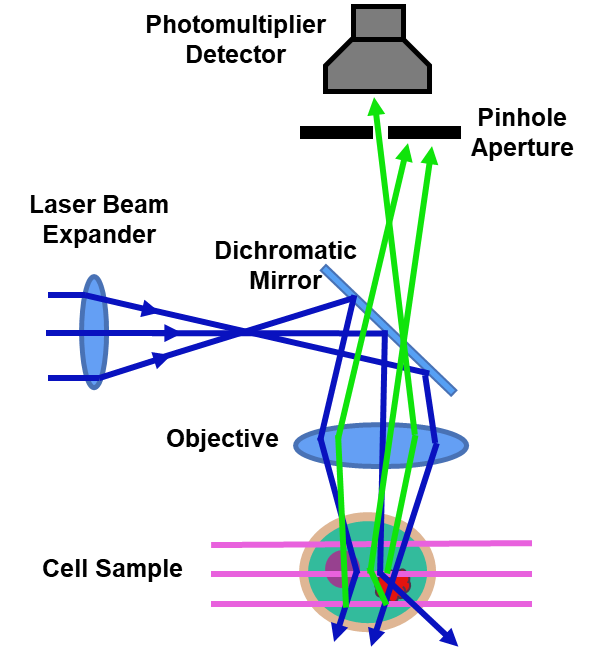

**ILL. 2.2 ***Confocal microscope using a pinhole that is conjugated to the probing spot to reject off-focus light.*

For 3D PSF, the total PSF

$h\left(x,y;z\right)=\eta \left(x,y;z\right)p\left(x,y;z\right)$,

where $\eta \left(x,y;z\right)$ is the sensor receptive function, which is the pinhole function convolved (2D) with the 3D incoherent PSF


$$\eta \left(x,y;z\right)=D\left(-x,-y\right)\otimes h_d \left(-x,-y;z\right)$$


$p\left(x,y;z\right)$ is illumination PSF. If using a single mode laser illumination that filled the full aperture of the same microscope objective, this can be modeled as a Gaussian beam with NA matching that of the objective NA. $p\left(x,y;z\right)\approx h_d \left(x,y;z\right)$.

***Example 2.1 Comparing the optical sectioning of confocal microscope and wide-field microscope***

The object is a hollow microsphere with an outer diameter of  $5\ldotp 6\;\mu m$. The NA of the objective is 0.6 and the lateral pixel size of the image is $\sim 0\ldotp 16\;\mu m$. For simplicity, we assume the pinhole size is smaller than the diffraction-limited spot size on the detector side. The sensor receptive function can be estimated using the 3D Gaussian propagation profile. Please feel free to change the *focus, *to observe the difference in optical sectioning.

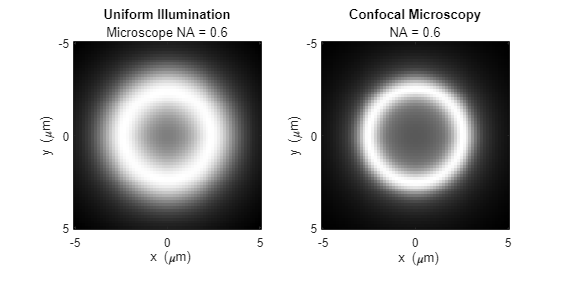

%% load the image
clear
close all
load microsphere.mat
%% Uniform illumniation 
lambda = 0.620; % emmission wavelength [Unit: um]
NA_d = 0.6;
% for simplicity, we use gaussian beam profile
focus =17; %which layer is the focus
w0_d = lambda/(pi*NA_d);
zR_d = w0_d/NA_d;
dx = x(2)-x(1);
I = zeros(nx,ny);
for ii = 1:nz 
    wz_d = w0_d*sqrt(1+(z(ii)-z(focus))^2/zR_d^2); % spot size parameter
    sigma = (wz_d/dx)^2; % gaussian blur variance in pixels
    % accumulating through depth stack
    I = I+imgaussfilt(Vol_sphere(:,:,ii), sigma);
end
%% Confocal
NA_i = 0.6; % illumniation NA
lambda_i = 0.532; % excitation wavelength
% for simplicity, we use gaussian beam profile
w0_i = lambda/(pi*NA_i);
zR_i = w0_i/NA_i; % rayleigh length in x direction
I_con = zeros(nx,ny);
for ii = 1:nz 
    wz_d = w0_d*sqrt(1+(z(ii)-z(focus))^2/zR_d^2); % spot size parameter
    wz_i = w0_i*sqrt(1+(z(ii)-z(focus))^2/zR_i^2); % illumniatin spot
    sigma_con = 1/((wz_d/dx)^-2+(wz_i/dx)^-2); % gaussian blur variance in pixels
    % accumulating through depth stack
    I_con = I_con+imgaussfilt(Vol_sphere(:,:,ii), sigma_con);
end
figure()
set(gcf,'Position', [100 100 600 300])
subplot(121)
colormap("gray")
imagesc(x,y, I)
axis image
title(['Uniform Illumination'],['Microscope NA = ', num2str(NA_d)])
xlabel(' x (\mum)')
ylabel('y (\mum)')
subplot(122)
colormap("gray")
imagesc(x,y, I_con)% please add x, y label with unit.
axis image
title(['Confocal Microscopy'], ['NA = ', num2str(NA_d)])
xlabel(' x (\mum)')
ylabel('y (\mum)')

The confocal microscope image has finer laterial and axial resolution.

### 2.3 Sheet illumination microscope

Light sheet fluorescent microscopy, illuminates the sample with a thin sheet of laser light while collecting fluorescence from the same focal plane. 

Light sheet microscopy provides excellent optical sectioning. The lateral resolution of optical microscopes is actually better than the axial directoin (see Lecture 6 for details). Using sheet illumination, only a specific focal plane was excited, rejecting out-of-focus light. This results in high-resolution 3D reconstructions with reduced background noise and improved contrast. 

Compared to confocal microscopy, it has the following additional advantages:

- Reduced phototoxicity: Light sheet microscopy uses a thin sheet of laser light to illuminate the sample from the slice, minimizing the exposure of the entire specimen to intense light. This reduces photodamage and photobleaching, making it suitable for long-term live-cell imaging and imaging of delicate or light sensitive samples.

- Fast imaging: Light sheet microscopy allows for rapid acquisition of 3D image stacks because it illuminates only the focal plane of interest, reducing acquisition time compared to techniques that can scan through the entire sample. This is particularly advantageous for capturing dynamic processes in real-time. 

Light sheet microscopy is well-suited for imaging live, large samples. It is mostly used for imaging whole organisms, tissues, or organs thanks to reduced photo-toxicity and high-speed full-field imaging.

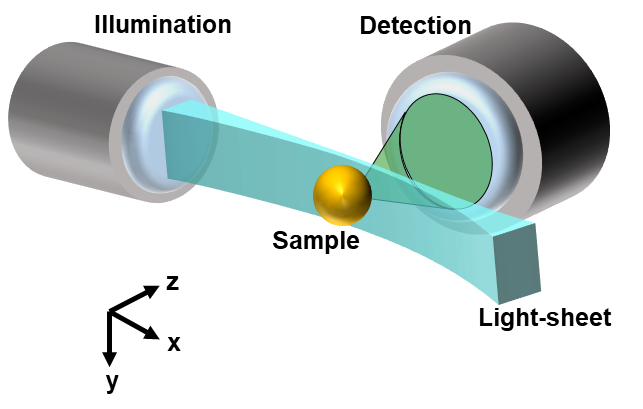

**ILL. 2.3 ***Light sheet microscope illuminates samples from the side. i.e., only the plane in focus is excited by the light sheet.*

***Example 2.2 Comparing the optical sectioning of a confocal microscope and light-sheet microscope***

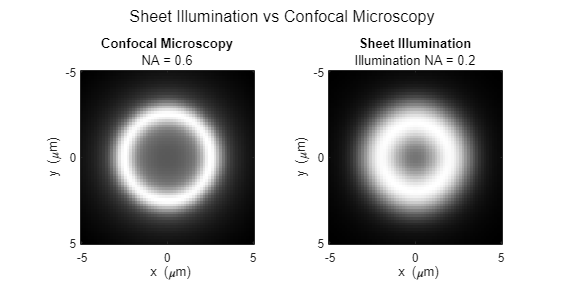

%% sheet illumination
NA_s = 0.2; % sheet illumniation NA
focus =17;
% for simplicity, we use gaussian beam profile
w0_s = lambda_i/(pi*NA_s);
xR_s = w0_s/NA_s;
[X,Y,Z] = ndgrid(x,y,z);
Sheet_illu = exp(-(Z-z(focus)).^2./(w0_s.^2.*(1+(X./xR_s).^2)));
Sphere_sheet = Vol_sphere.*Sheet_illu; % sheet illuminated sphere
I_si = zeros(nx,ny);

for ii = 1:nz 
    wz_d = w0_d*sqrt(1+(z(ii)-z(focus))^2/zR_d^2); % spot size parameter
    sigma = (wz_d/dx)^2; % gaussian blur variance in pixels
    % accumulating through depth stack
    I_si = I_si + imgaussfilt(Sphere_sheet(:,:,ii), sigma);
end
%Comparison of confocal, wide-field, and light-sheet
figure()
sgtitle('Sheet Illumination vs Confocal Microscopy')
set(gcf,'Position', [100 100 600 300])

subplot(121)
colormap("gray")
imagesc(x,y, I_con)
axis image
title(['Confocal Microscopy'], ['NA = ', num2str(NA_d)])
xlabel(' x (\mum)')
ylabel('y (\mum)')

subplot(122)
colormap("gray")
imagesc(x,y, I_si)
axis image
xlabel(' x (\mum)')
ylabel('y (\mum)')
title(['Sheet Illumination'],['Illumination NA = ', num2str(NA_s)])

Compared with confocal microscope, sheet illumination has lower lateral resolution. However, the signal from the axial direction is supressed, leading to a better signal to background ratio, as can be observed in the center part of the image.

## **3. Spatial super resolution microscope**

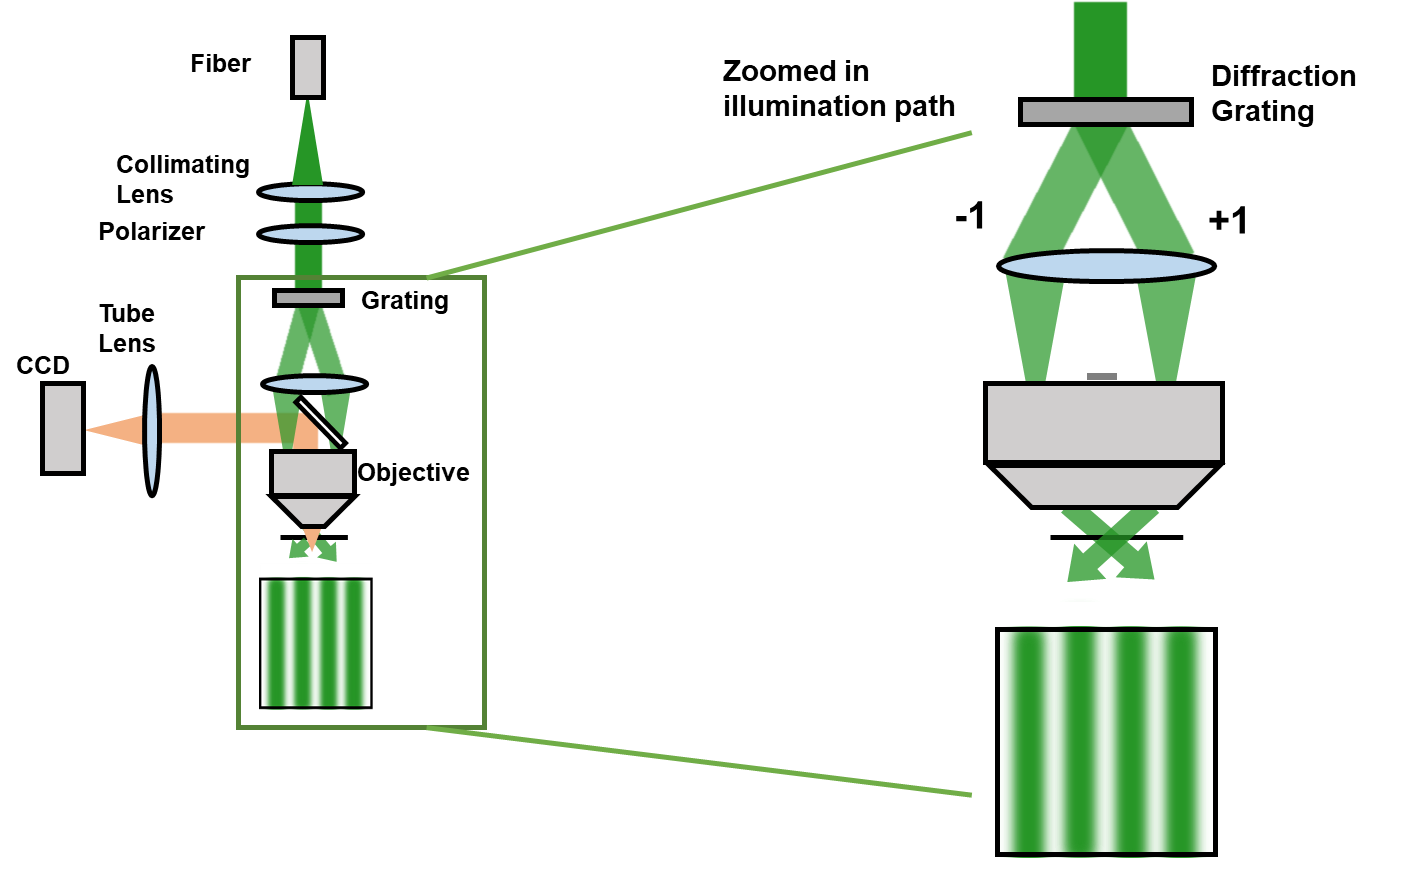

**ILL. 3.1 ***Structured illumination microscopes impose a periodical patterned light on to the sample. The detection path is the same as conventional epi-illumination fluorescent microscopes.*

Structured Illumination Microscopy (SIM) for the super-resolution generally works by illuminating the sample with patterned light, and then images are taken at different phases and orientations of the light pattern. By combining these images, one can synthetically reconstruct a high-resolution image. The setup of the SIM is shown in ILL 3.1 The setup is similar to the wide-field epi-illumination microscope, except that a grating is inserted in the illumination path to create a sinusoidal illumination pattern by interfering the diffracted beam of +1 and -1 orders.

### 3.1 Operation principle: Thinking in K-space

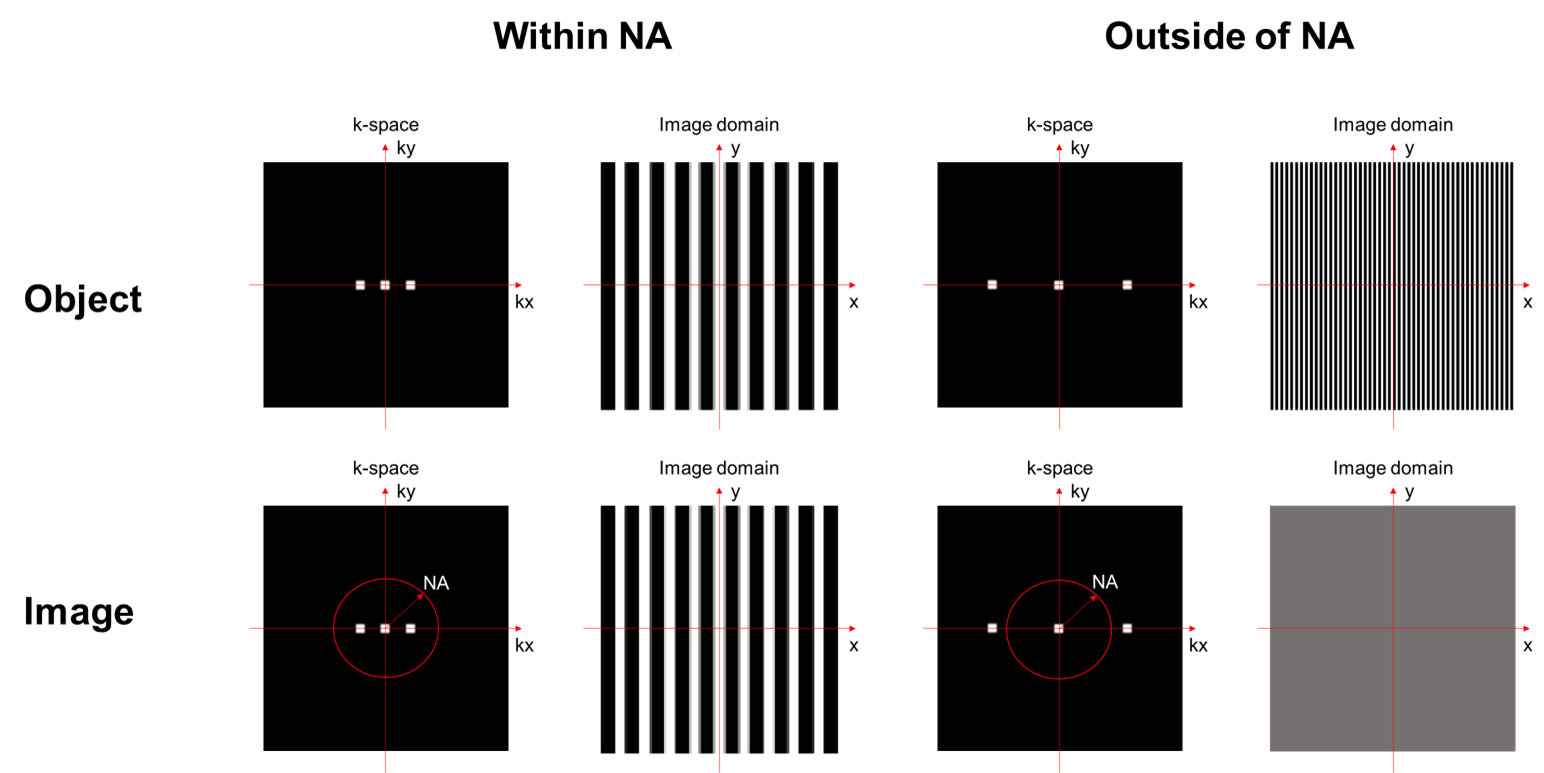

**ILL. 3.2 ***The NA of the microscope objective limits the bandwidth of the frequency can be resolved. This is the fundamental limit of the wide-field microscope.*

The microscope objective NA is the frequency support in k-space. The object with frequency greater than $\frac{1}{\rho_{\alpha } }=\frac{2\textrm{NA}}{\lambda }$ does not have any contrast in the image, shown in ILL. 3.2.

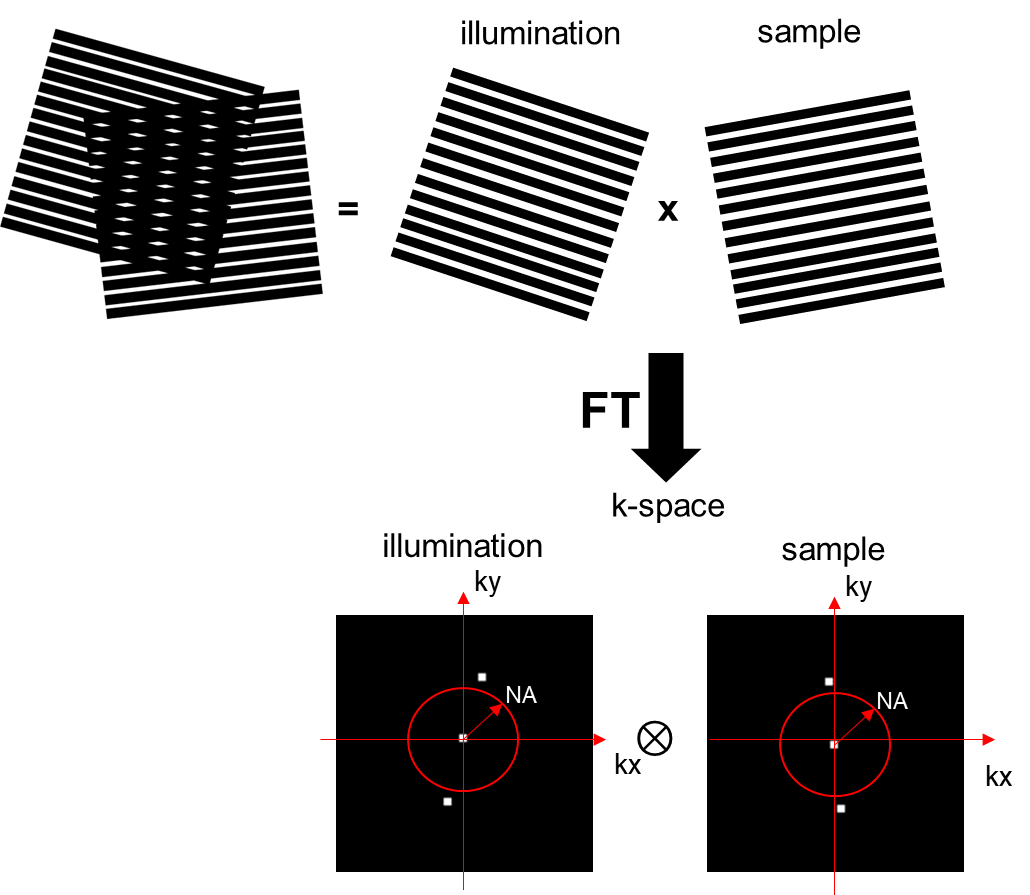

**ILL. 3.3 ***A Moire pattern occurs when two periodic grids are overlaid on each other and patterns with a new period appear.*

The key principle of structured illumination microscopy is to project a periodic pattern of light onto the sample, which shift the high-frequency information that is outside of the NA of the objective into the detectable range. This phenomena of frequency shifting by imposing a periodic pattern is known as the Moire pattern, which has been used in metrology to measure small angular rotation for a long time. ILL. 3.3 illustrates this phenomena in the frequency domain as well. The product of the illumination pattern and sample pattern in the spatial domain is equivalent to a convolution of the two frequency patterns in k-space.

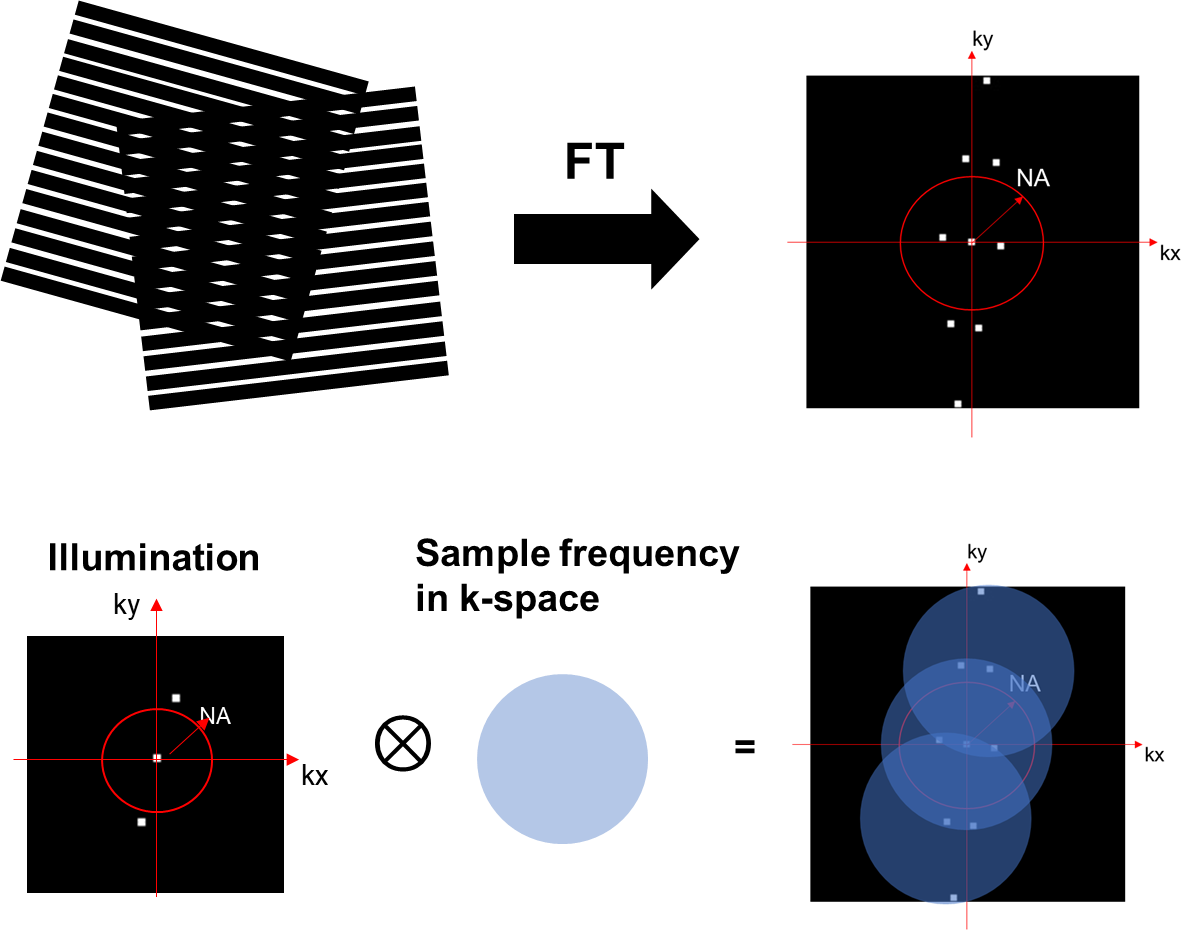

**ILL. 3.4 ***The convolution of two frequencies outside of the NA range can generate a frequency that can be resolved.*

For a sinusoidal periodic pattern (i.e., $\sin \left({\mathbf{k}}_1 \cdot \mathbf{r}\right)$with spatial frequency ${\mathbf{k}}_1$. There are three frequency components at ${\mathbf{k}}_1 ,{-\mathbf{k}}_1$, and $0$. When convolving with another sinusoidal pattern, say $\sin \left({\mathbf{k}}_2 \cdot \mathbf{r}\right)$, there will be a total of $3\textrm{x3}$ frequency components. Other than the DC ($0$ frequency) components, there are two frequency components $\left({\mathbf{k}}_1 -{\mathbf{k}}_2 \right)$and $-\left({\mathbf{k}}_1 -{\mathbf{k}}_2 \right)$, that fall within the NA of the detection. If we are looking at a general object with a continuous frequency distribution, the structured illumination essentially creates a super-position of the original frequency and two shifted versions with ${\mathbf{k}}_1$ and ${-\mathbf{k}}_1$ respectively in the k-space. This concept is shown in ILL. 3.4.

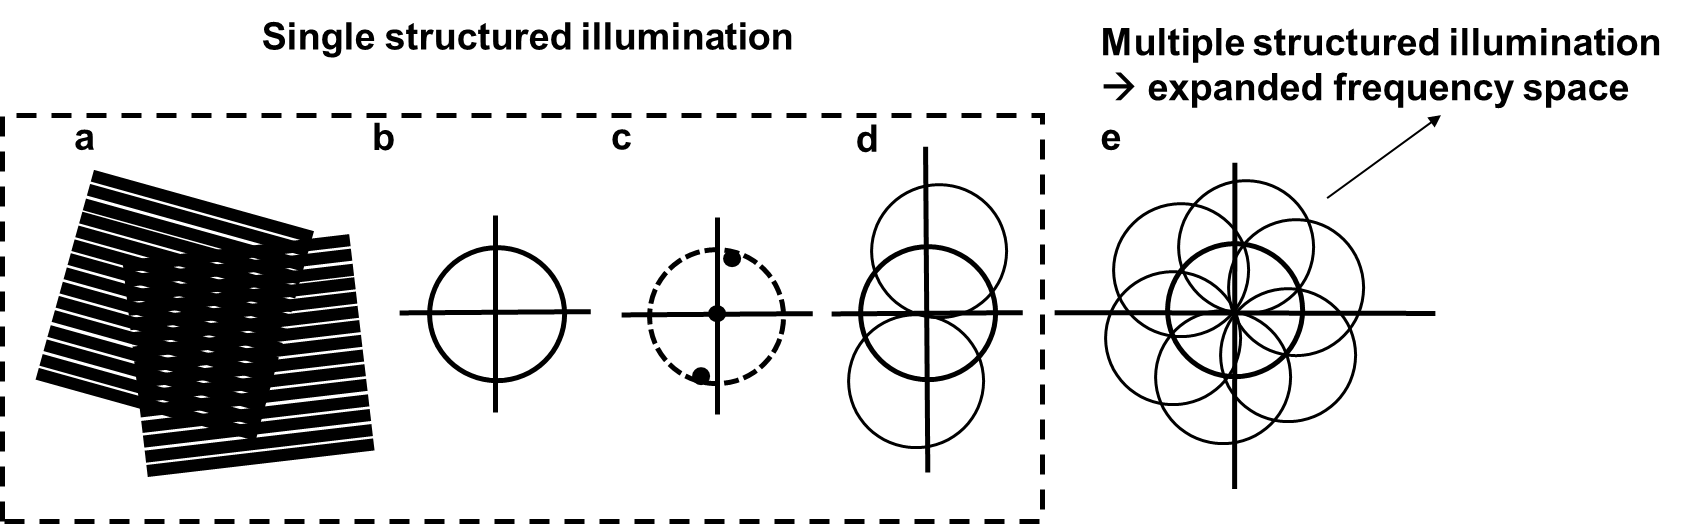

**ILL. 3.5 ***The convolution of two frequency that is outside of the NA range can generate frequency that can be resolved*

To fill up the extended k-space, the common practices are

- Picking the illumination pattern that contains the frequency matching the NA support fo the objective (ILL. 3.5 (c)), this will result in a frequency extension to 2 times the original NA (ILL. 3.5 (d)) 

- Introducing both sine and cosine illumination of a given rotation angle, so that the positve and negative frequency components can be separated in reconstruction. 

- Adding at least 3 angles of illumination (usually $0^{\circ }$, ${60}^{\circ }$, and ${120}^{\circ }$), so that the extended frequency range is not sparse. More angles can also be introduced to reduce the unfilled area.

### **3.2 Reconstruction**

Reconstruction of structured illumination super-resolution requires combing the frequency shifted measurement in k-space. Example 3.1 is an example code for generating structured illumination measurement and reconstruction. In brief, the reconstruction has 4 steps:

- Load low-resolution image and the images with structured ilumination (at least 6, with angular step size of ${60}^{\circ }$ in k-space).

- Retrieve the high-frequency spatial information: for each low-resolution image, demodulate the image by multiplying it with the corresponding shifted illumination pattern to retrieve high-frequency components. Fourier transform the demodulated images, and store the extracted high-frequency information. 

- Reconstruct the super-resolved image: combine the extracted high-frequency components from each of the low-resolution images into the Fourier space.

- Inverse Fourier transform the combined high-frequency information to obtain the super-resolved image in real space.

In many cases, preprocessing and post processing is needed. The preprocessing on the low-resolution measurement is intended to correct for any aberrations or misalignments in the images. Post-processing is required for correcting for any artifacts introduced during the reconstruction (like noise or ghost images) and adjusting the contrast and brightness for better visualization.

***Example 3.1 ***

Structured illumination super-resolution fluorescent microscope and image reconstruction

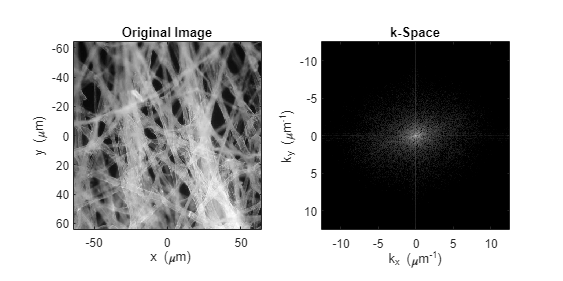

%% load image
clear
Img = double(imread('fiber.tiff'));
[nx,ny] = size(Img);
dx = 0.25; % resolution [unit: um]
x = dx*(-nx/2:nx/2-1)+dx/2;
y = dx*(-ny/2:ny/2-1)+dx/2;
[X,Y] = ndgrid(x,y);
% frequency coordinate
dkx = 2*pi/(dx*nx);
dky = 2*pi/(dx*ny);
kx = (-nx/2:(nx/2-1))*dkx;
ky = (-ny/2:(ny/2-1))*dky;
[Kx,Ky] = ndgrid(kx,ky);

Img_h = fftshift(fft2(fftshift(Img)));
figure()
set(gcf,'Position', [100 100 600 300])
subplot(121)
imagesc(x,y,Img), colormap("gray")
axis image
title('Original Image')
xlabel(' x (\mum)')
ylabel('y (\mum)')

subplot(122)
imagesc(kx,ky,abs(Img_h)), 
set(gca,'ColorScale','log')
axis image
title('k-Space')
xlabel('k_x (\mum^{-1})')
ylabel('k_y (\mum^{-1})')

The frequency components of the original image span the whole k-space.  

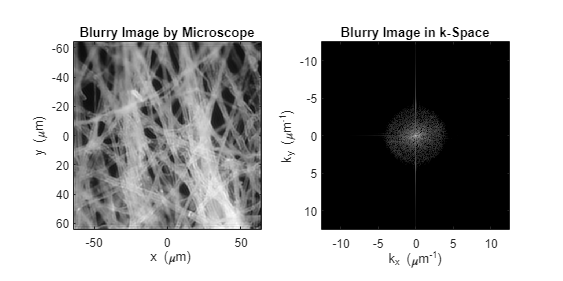

%% create the blur kernel
lambda = 0.632; % wavelength [unit:um]
na = 0.4; % numerical aperture

n_k = 32; % size of the kernel
x_k = dx*(-n_k/2:n_k/2-1)+dx/2;
y_k = dx*(-n_k/2:n_k/2-1)+dx/2;
[X_k, Y_k] = ndgrid(x_k,y_k);
Rho = sqrt(X_k.^2 + Y_k.^2); % radio coordinate
rho_a = lambda/2/na;
h = 2*besselj(1,pi.*Rho/rho_a)./(pi.*Rho./rho_a);
Imgb = conv2(Img, h,"same");
Imgb_h = fftshift(fft2(fftshift(Imgb)));

figure()
set(gcf,'Position', [100 100 600 300])
subplot(121)
imagesc(x,y,Imgb)
colormap("gray")
axis image
title('Blurry Image by Microscope')
xlabel(' x (\mum)')
ylabel('y (\mum)')
subplot(122)
imagesc(kx,ky,abs(Imgb_h)), 
set(gca,'ColorScale','log')
axis image
title('Blurry Image in k-Space')
xlabel('k_x (\mum^{-1})')
ylabel('k_y (\mum^{-1})')

The frequency components of the blurry image is limited by the numerical aperture (na = 0.4) of the microscope objective.

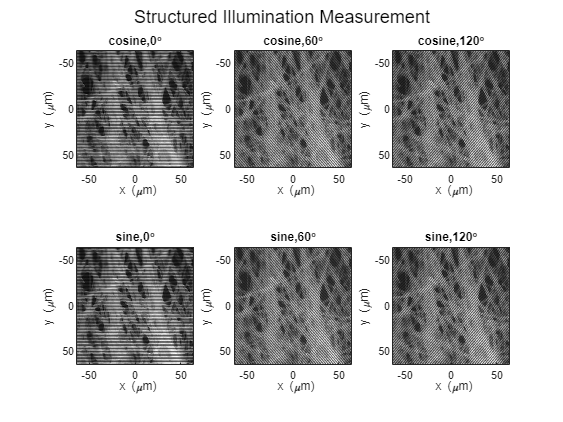

%% structured illumination 
theta = [0, pi/3, 2*pi/3];
theta_D = rad2deg(theta);
n_theta = length(theta);
kx_il = pi/rho_a.*cos(theta);
ky_il = pi/rho_a.*sin(theta);
Img_cos = zeros(nx,nx,n_theta);
Img_sin = zeros(nx,nx,n_theta);

for ii = 1:n_theta
    % illumination pattern
    il_c = 1+cos(kx_il(ii).*X+ky_il(ii).*Y);
    il_s = 1+sin(kx_il(ii).*X+ky_il(ii).*Y);
    % measurement
    Img_cos(:,:,ii) = conv2(il_c.*Img, h,"same");
    Img_sin(:,:,ii) = conv2(il_s.*Img, h,"same");
end
figure
figure()
sgtitle('Structured Illumination Measurement')
set(gcf,'Position', [100 100 600 450])
% measured images with structured illumination
colormap('gray')
for ii = 1:n_theta
    subplot(2,n_theta,ii)
    imagesc(x,y,squeeze(Img_cos(:,:,ii)))
    title(['cosine,',num2str(theta_D(ii)),'\circ'])
    axis image
    xlabel(' x (\mum)')
    ylabel('y (\mum)')
    subplot(2,n_theta,ii+n_theta)
    imagesc(x,y,squeeze(Img_sin(:,:,ii)))
    title(['sine,',num2str(theta_D(ii)), '\circ'])
    axis image
    xlabel(' x (\mum)')
    ylabel('y (\mum)')
end

Using the sine and cosine illuminations of the three angles gives positive and negative frequency components that can be separated in reconstruction. The use of three illumination angles provide a sufficient extended frequency range.

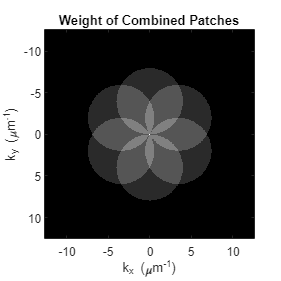

%% reconstruction
Img_b = conv2(Img, h,"same"); % no structure
Rec_p = zeros(nx,ny);
Rec_n = zeros(nx,ny);
Rec_accu_h = zeros(nx,ny); % accumulated stitched frequency 
Ind_accu_h = zeros(nx,ny); % weighted 
for ii = 1:n_theta
    Rec_p = ((Img_cos(:,:,ii)-Img_b)+(Img_sin(:,:,ii)-Img_b)*1i).*...
        exp(-1i.*(kx_il(ii).*X+ky_il(ii).*Y)); % reconstruction positive
    Rec_n = ((Img_cos(:,:,ii)-Img_b)-(Img_sin(:,:,ii)-Img_b)*1i).*...
        exp(1i.*(kx_il(ii).*X+ky_il(ii).*Y)); % reconstruction negative

    Rec_p_h = fftshift(fft2(fftshift(Rec_p)));
    Rec_n_h = fftshift(fft2(fftshift(Rec_n)));
    % freuqency support
    Ind_p_h = zeros(nx, ny);
    Ind_p_h((Kx+kx_il(ii)).^2+(Ky+ky_il(ii)).^2<=(pi/rho_a)^2)=1;
    Ind_n_h = zeros(nx, ny);
    Ind_n_h((Kx-kx_il(ii)).^2+(Ky-ky_il(ii)).^2<=(pi/rho_a)^2)=1;
    % accumulation of each freqeuncy patches
    Rec_accu_h = Rec_accu_h+Rec_p_h.*Ind_p_h+Rec_n_h.*Ind_n_h;
    Ind_accu_h = Ind_accu_h+Ind_p_h+Ind_n_h;
end
Rec_support_h = Ind_accu_h>0;
Rec_h = zeros(nx,ny);
Rec_h(Rec_support_h)=Rec_accu_h(Rec_support_h)./Ind_accu_h(Rec_support_h);
Rec = fftshift(ifft2(fftshift(Rec_h)));

figure()
set(gcf,'Position', [100 100 300 300])
colormap("gray")
imagesc(kx,ky,Ind_accu_h)
axis image
title('Weight of Combined Patches')
xlabel('k_x (\mum^{-1})')
ylabel('k_y (\mum^{-1})')

The convolution of the frequency components can be seen above, as a result of the multiple illumination angles.

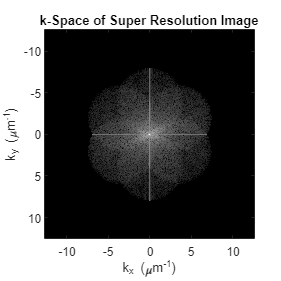

figure()
set(gcf,'Position', [100 100 300 300])
colormap("gray")
imagesc(kx,ky,abs(Rec_accu_h))
set(gca,'ColorScale','log')
axis image
title('k-Space of Super Resolution Image')
xlabel('k_x (\mum^{-1})')
ylabel('k_y (\mum^{-1})')

The k-space shown above depicts the expanded frequency space of the super resolution image. It can be seen that the area is no longer limited by the numerical aperture of the microscope objective.

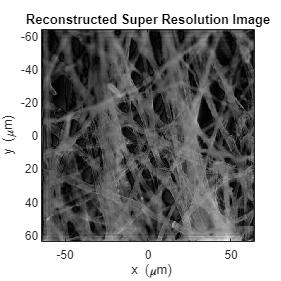

figure()
set(gcf,'Position', [100 100 300 300])
colormap("gray")
imagesc(x,y,abs(Rec))
axis image
title('Reconstructed Super Resolution Image')
xlabel(' x (\mum)')
ylabel('y (\mum)')

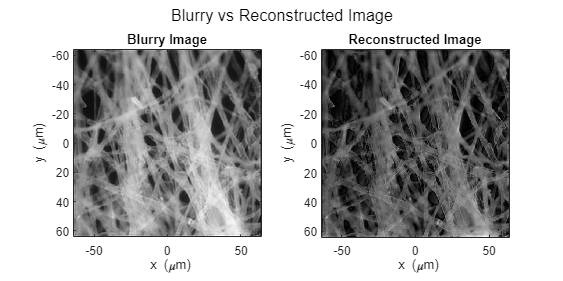

% original, blurred and reoconstruction comparison.
figure()
set(gcf,'Position', [100 100 600 300])

sgtitle('Blurry vs Reconstructed Image')

subplot(121)
imagesc(x,y,Imgb)
colormap("gray")
axis image
title('Blurry Image')
xlabel(' x (\mum)')
ylabel('y (\mum)')

subplot(122)
imagesc(x,y,abs(Rec))
axis image
title('Reconstructed Image')
xlabel(' x (\mum)')
ylabel('y (\mum)')

The reconstructed image has a noticeably higher resolution than the blurry image.